N=150;
wc=2*70/N;%frec corte dig normalizada
h=fir1(N,wc,'high');%paso altas
fo=50;
fl=fo-1;
fh=fo+1;
wc=2*[fl fh]/N;
h2=fir1(N,wc);%pasa
h3=fir1(N,wc,'stop');%sup
[H,w]=freqz(h,1,N/2);%El espectro se grafia en M puntos donde M es la mitad del espectro
[H2,w]=freqz(h2,1,N/2);
[H3,w]=freqz(h3,1,N/2);

n=2;%IIR
[b,a]=butter(n,wc,'stop')

b =     0.9425    1.8866    2.8291    1.8866    0.9425


a =     1.0000    1.9425    2.8258    1.8307    0.8883


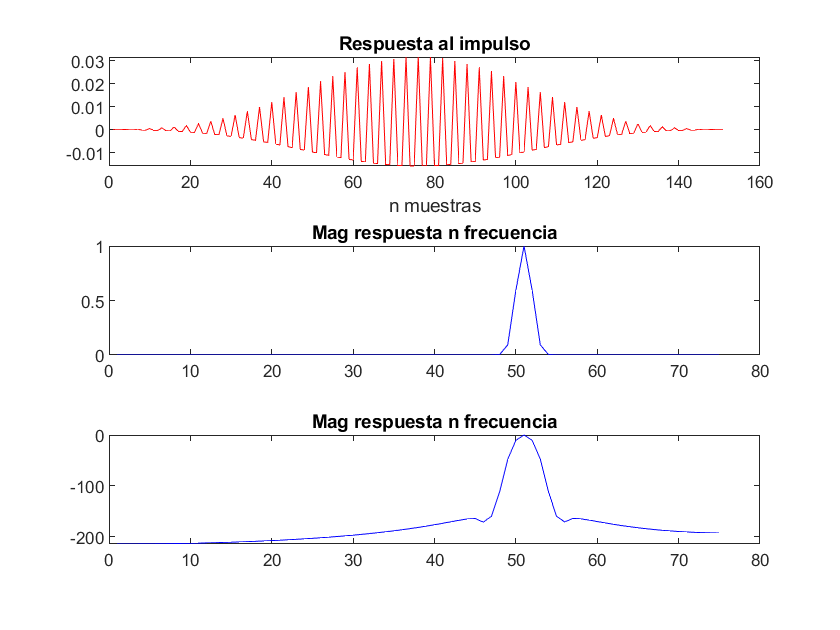

[H4,w]=freqz(b,a,N/2);

figure(1)
subplot(311)
plot(h,'r')
title('Respuesta al impulso')
xlabel('n muestras')
subplot(312)
plot(abs(H),'b')
title('Mag respuesta n frecuencia')
subplot(313)
plot(20*log(abs(H)),'b')
title('Mag respuesta n frecuencia')

figure(2)
subplot(311)
plot(h2,'r')
title('Respuesta al impulso')
xlabel('n muestras')
subplot(312)
plot(abs(H2),'b')
title('Mag respuesta n frecuencia')
subplot(313)
plot(20*log(abs(H2)),'b')
title('Mag respuesta n frecuencia')

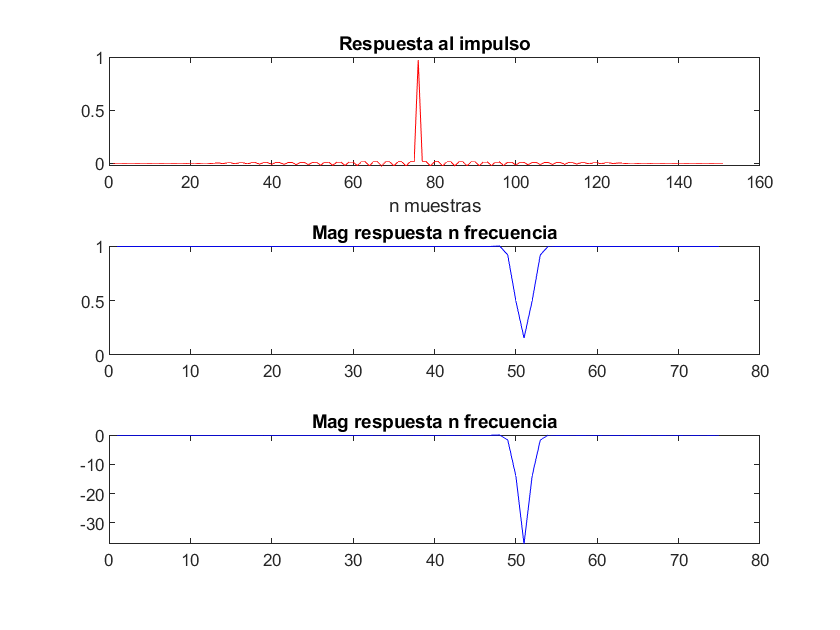


figure(3)
subplot(311)
plot(h3,'r')
title('Respuesta al impulso')
xlabel('n muestras')
subplot(312)
plot(abs(H3),'b')
title('Mag respuesta n frecuencia')
subplot(313)
plot(20*log(abs(H3)),'b')
title('Mag respuesta n frecuencia')

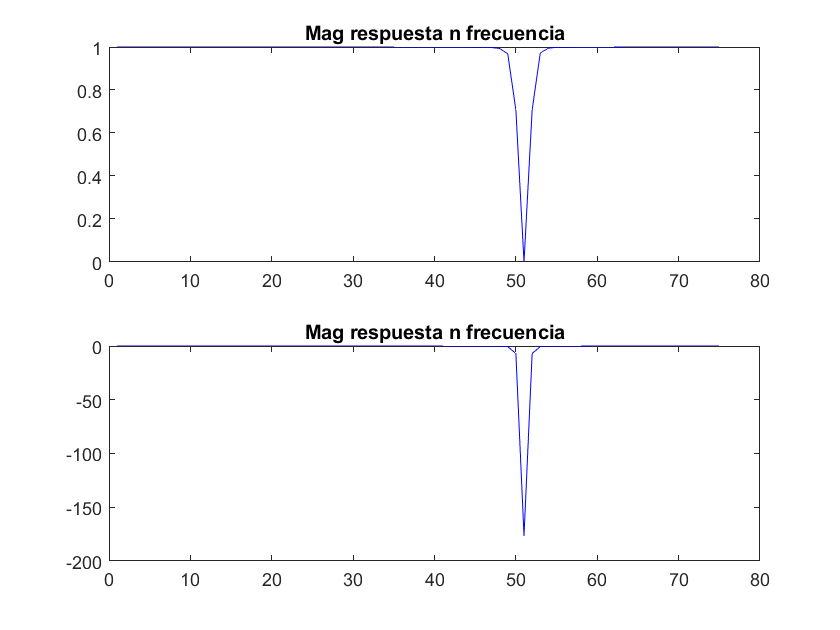


figure(4)
subplot(211)
plot(abs(H4),'b')
title('Mag respuesta n frecuencia')
subplot(212)
plot(20*log(abs(H4)),'b')
title('Mag respuesta n frecuencia')